clear all;

## Описание задачи

lambda = -8; kappa = 3; mu = sqrt(10); sigma = sqrt(4);
F= @(t,y,z) lambda*y + kappa*z(1,1);  G = @(t,y,z) mu*y + sigma*z(1,1);
history = @(t,y) 1;
delay = 2;
% z(i, j) - i это номер запаздывающей переменной,
% j - номер коэф. запаздывания
% sdde = @(t,y) F(t,y,z)dt + G(t,y,z)dW;

t_0 = 0;
Yzero = 1;

Запаздывание в основной часте

% lambda = -1; mu = -1.5;
% F = @(t,y,z) lambda*y+z(1,1); 
% G = @(t,y,z) mu*y;
% history = @(t) [1; 1];
% delay = [1/2, 1/10];
% 
% t_0 = 0;
% Yzero = 1;

Запаздывание стохастической части

% lambda = -1; mu = -1.5;
% F = @(t,y,z) lambda*y; 
% G = @(t,y,z) mu*y+z(1,1);
% history = @(t) [1; 1];
% delay = [1/2, 1/10];
% 
% t_0 = 0;
% Yzero = 1;

Запаздывание в обеих частях

% lambda = -1; mu = -1.5;
% F = @(t,y,z) [lambda*y(2)+z(1,1); 1/lambda+y(1)+z(2,2)]; 
% G = @(t,y,z) [mu*y(1)+z(1,2); 1/mu*y(2)+z(1,2)];
% history = @(t) [1; 1];
% delay = [1/2, 1/2];
% 
% t_0 = 0;
% Yzero = [1; 1];

Начальные условия

h = 1/4;
rightBorder = 5;

## Решение и построение графиков

[T, Y] = EulerMaruyama_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder);
[T1, Y1] = ROCK_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder, 4, 2);
[T2, Y2] = ROCK_SDDE2(F, G, h, t_0, Yzero, delay, history, rightBorder, 4, 2);
figure
plot (T, Y, 'red');
hold on
plot (T1, Y1, 'blue')
plot (T2, Y2, 'green')
legend("Euler-Maruyama", "ROCK1", "ROCK2");

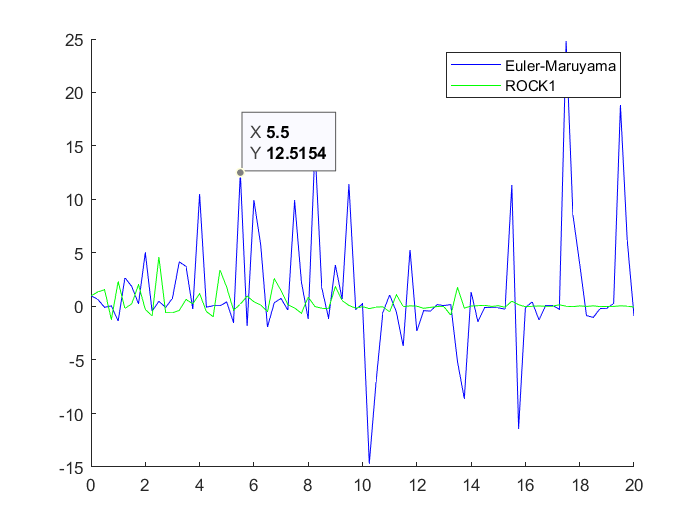

hold off

Проверка сходимости

rightBorder = 40;
%Параметры ROCK-метода
s = 4; eta = 3;
numExp = 50;

for i=1:numExp
    [Tem, Yem(i,:)] = EulerMaruyama_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder);
end

for i=1:length(Tem)
    meanYem(i) = mean(Yem(:,i).^2);
end

for i=1:numExp
    [Trock, Rock(i,:)] = ROCK_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder, s, eta);
end

for i=1:length(Trock)
    meanYrock(i) = mean(Rock(:,i).^2);
end

for i=1:numExp
    [Trock2, Rock2(i,:)] = ROCK_SDDE2(F, G, h, t_0, Yzero, delay, history, rightBorder, s, eta);
end

for i=1:length(Trock2)
    meanYrock2(i) = mean(Rock2(:,i).^2);
end

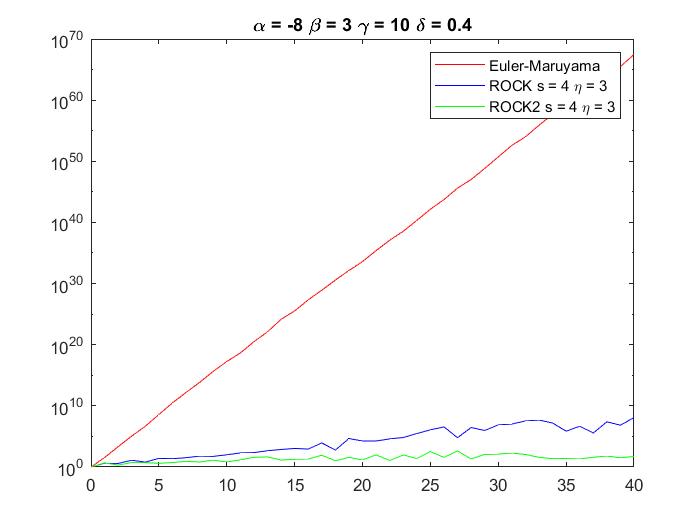

figure
semilogy(Tem, meanYem , "red");
hold on
semilogy(Trock, meanYrock , "blue");
semilogy(Trock2, meanYrock2 , "green");
title([['\alpha = ' num2str(h*lambda)] [' \beta = ' num2str(h*kappa)] ...
    [' \gamma = ' num2str(h*mu^2)] [' \delta = ' num2str(h*sigma^2)]]);
legend(['Euler-Maruyama'], ['ROCK s = ' num2str(s) ' \eta = ' num2str(eta) ], ...
    ['ROCK2 s = ' num2str(s) ' \eta = ' num2str(eta) ]);
hold off